# **Wireless Communications**

# **CA#2 **

## Sogol Goodarzi

## 810198467

## Section 2. Frequency Selective Channel

### Question 5. 

clc;
clear all;
N = 5*1e6;
nc = 1e4;
cp = 199;
block_num = N/nc;
n = 10;
m = 10;   % mrc diversity number
SNR = linspace(-20,20,n);
p_max = nc;
N0 = p_max./(10.^(SNR./10)*nc);
pe = zeros(1,n);
% Generate bits:
bits = randi([0,1],1,N);
% Generate blocks:
blocks = reshape(bits,block_num,nc);
% BPSK Modulation:
a = dpskmod(blocks,2);





### Question 6.  

#### BER with MRC in receiver

clc;
clear all;
N = 5*1e6;
nc = 1e4;
cp = 199;
block_num = N/nc;
n = 10;
m = 10;   % mrc diversity number
SNR = linspace(-20,20,n);
p_max = nc;
N0 = p_max./(10.^(SNR./10)*nc);
pe = zeros(1,n);
% Generate bits:
bits = randi([0,1],1,N);
% Generate blocks:
blocks = reshape(bits,block_num,nc);
% BPSK Modulation:
a = dpskmod(blocks,2);
% IFFT:
A = ifft(a,nc,2);
% Adding cp:
x = CP(cp, A);
% Creating the channel:
for itr = 1:n
    Z = zeros(block_num,nc);
    for i = 1:block_num
        h_Re = sqrt(1/2)*randn(1,cp+1,m);
        h_Im = sqrt(1/2)*randn(1,cp+1,m);
        h = h_Re + 1j*h_Im;
        w_Re = sqrt(N0(itr)/2).*randn(1,length(x(1,:)),m);
        w_Im = sqrt(N0(itr)/2).*randn(1,length(x(1,:)),m);
        w = w_Re +1j*w_Im;
        Z_ = zeros(1,nc,m);
        for k = 1:m
            % Channel:
            y_ = cconv(x(i,:),h(:,:,k),length(x(i,:)))+ w(:,:,k);
            % cp removal:
            y = CP_Removal(cp, y_);
            % FFT:
            Y = fft(y,nc);

#### MRC in Receiver:

#### cophasing and removing channel effect:

#### 
$$y=|h|^2 x+h^* w$$


#### As we use MRC after FFT block so we multiply $H^*$to $Y$signal. 

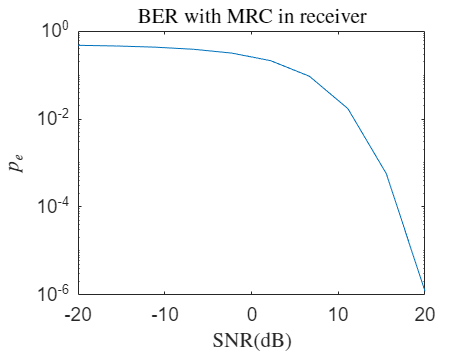

            % MRC:
            H = fft(h(:,:,k),nc);
            Z_(1,:,k) = Y.*conj(H);
        end
        Z(i,:) = sum(Z_,3);
    end
    Z = reshape(Z,1,nc*block_num);
    a = reshape(a,1,nc*block_num);
    pe(itr) = sum(Z.*a<0)/(block_num*nc);
end
semilogy(SNR,pe);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('BER with MRC in receiver',Interpreter='latex');

### **Question 7. **

####  **BER with ZF equalizer**

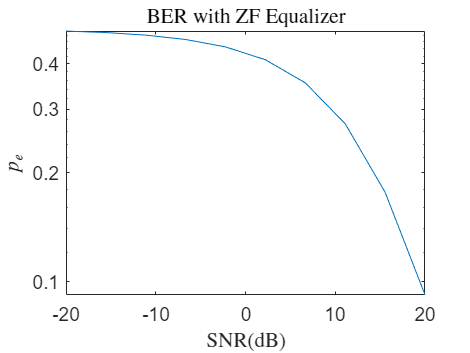

clc;
clear all;
N = 5*1e6;
nc = 1e4;
cp = 199;
block_num = N/nc;
n = 10;
SNR = linspace(-20,20,n);
p_max = nc;
N0 = p_max./(10.^(SNR./10)*nc);
pe_ZF = zeros(1,n);
% Generate bits:
bits = randi([0,1],1,N);
% Generate blocks:
blocks = reshape(bits,block_num,nc);
% BPSK Modulation:
a = dpskmod(blocks,2);
% IFFT:
A = ifft(a,nc,2);
% Adding cp:
x = CP(cp, A);
% Creating the channel:
for itr = 1:n
    Z = zeros(block_num,nc);
    for i = 1:block_num
        h_Re = sqrt(1/2)*randn(1,cp+1);
        h_Im = sqrt(1/2)*randn(1,cp+1);
        h = h_Re + 1j*h_Im;
        w_Re = sqrt(N0(itr)/2).*randn(1,length(x(1,:)));
        w_Im = sqrt(N0(itr)/2).*randn(1,length(x(1,:)));
        w = w_Re +1j*w_Im;
        % Channel:
        y_ = cconv(x(i,:),h,length(x(i,:)))+ w;
        % cp removal:
        y = CP_Removal(cp, y_);
        % FFT:
        Y = fft(y,nc);
        % ZF equalizer:
        H = fft(h,nc);
        Z(i,:) = Y.*1./H;
    end
    Z = reshape(Z,1,nc*block_num);
    a = reshape(a,1,nc*block_num);
    pe_ZF(itr) = sum(Z.*a<0)/(block_num*nc);
end
semilogy(SNR,pe_ZF);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('BER with ZF Equalizer',Interpreter='latex');

####  **BER with MMSE equalizer**

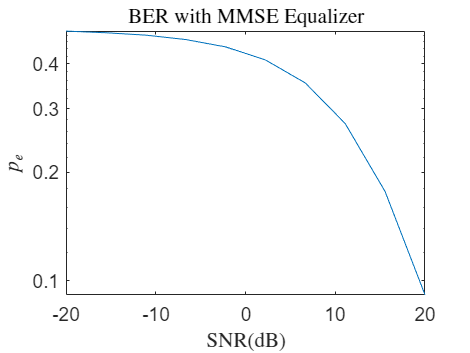

pe_MMSE = zeros(1,n);
% Generate bits:
bits = randi([0,1],1,N);
% Generate blocks:
blocks = reshape(bits,block_num,nc);
% BPSK Modulation:
a = dpskmod(blocks,2);
% IFFT:
A = ifft(a,nc,2);
% Adding cp:
x = CP(cp, A);
% Creating the channel:
for itr = 1:n
    Z = zeros(block_num,nc);
    for i = 1:block_num
        h_Re = sqrt(1/2)*randn(1,cp+1);
        h_Im = sqrt(1/2)*randn(1,cp+1);
        h = h_Re + 1j*h_Im;
        w_Re = sqrt(N0(itr)/2).*randn(1,length(x(1,:)));
        w_Im = sqrt(N0(itr)/2).*randn(1,length(x(1,:)));
        w = w_Re +1j*w_Im;
        % Channel:
        y_ = cconv(x(i,:),h,length(x(i,:)))+ w;
        % cp removal:
        y = CP_Removal(cp, y_);
        % FFT:
        Y = fft(y,nc);
        % MMSE equalizer:
        H = fft(h,nc);
        sigma2_n = repmat(N0(itr), [1, nc]);
        W = conj(H)./((H.*conj(H))+sigma2_n);
        Z(i,:) = Y.*W;
    end
    Z = reshape(Z,1,nc*block_num);
    a = reshape(a,1,nc*block_num);
    pe_MMSE(itr) = sum(Z.*a<0)/(block_num*nc);
end
semilogy(SNR,pe_MMSE);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('BER with MMSE Equalizer',Interpreter='latex');

#### Compare two equalizers (ZF & MMSE):

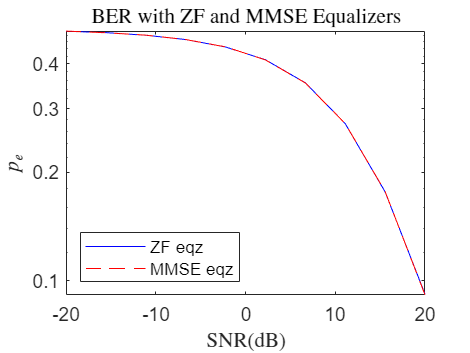

semilogy(SNR,pe_ZF,'b',SNR,pe_MMSE,'r--');
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
legend(["ZF eqz", "MMSE eqz"],'Location','southwest');
title('BER with ZF and MMSE Equalizers',Interpreter='latex');

### **Question 8. **

#### **MMSE equalizer without clipping**

clc;
clear all;
N = 5*1e6;
nc = 1e4;
cp = 199;
block_num = N/nc;
n = 10;
SNR = linspace(-20,20,n);
p_max = nc;
N0 = p_max./(10.^(SNR./10)*nc);
pe_MMSE = zeros(1,n);
% Generate bits:
bits = randi([0,1],1,N);
% Generate blocks:
blocks = reshape(bits,block_num,nc);
% BPSK Modulation:
a = dpskmod(blocks,2);
% IFFT:
A = ifft(a,nc,2);
% Adding cp:
x = CP(cp, A);
% Creating the channel:
for itr = 1:n
    Z = zeros(block_num,nc);
    for i = 1:block_num
        h_Re = sqrt(1/2)*randn(1,cp+1);
        h_Im = sqrt(1/2)*randn(1,cp+1);
        h = h_Re + 1j*h_Im;
        w_Re = sqrt(N0(itr)/2).*randn(1,length(x(1,:)));
        w_Im = sqrt(N0(itr)/2).*randn(1,length(x(1,:)));
        w = w_Re +1j*w_Im;
        % Channel:
        y_ = cconv(x(i,:),h,length(x(i,:)))+ w;
        % cp removal:
        y = CP_Removal(cp, y_);
        % FFT:
        Y = fft(y,nc);
        % MMSE equalizer:
        H = fft(h,nc);
        sigma2_n = repmat(N0(itr), [1, nc]);
        W = conj(H)./((H.*conj(H))+sigma2_n);
        Z(i,:) = Y.*W;
    end
    Z = reshape(Z,1,nc*block_num);
    a = reshape(a,1,nc*block_num);
    pe_MMSE(itr) = sum(Z.*a<0)/(block_num*nc);
end

#### **MMSE equalizer with clipping**

pe_MMSE_Clip = zeros(1,n);
% Generate bits:
bits = randi([0,1],1,N);
% Generate blocks:
blocks = reshape(bits,block_num,nc);
% BPSK Modulation:
a = dpskmod(blocks,2);
% IFFT:
A = ifft(a,nc,2);
% Clipping:
thr = 0.8*max(max(abs(A)));
A = A.*(A < thr) + thr*(A > thr | A == thr);
% Adding cp:
x = CP(cp, A);
% Creating the channel:
for itr = 1:n
    Z = zeros(block_num,nc);
    for i = 1:block_num
        h_Re = sqrt(1/2)*randn(1,cp+1);
        h_Im = sqrt(1/2)*randn(1,cp+1);
        h = h_Re + 1j*h_Im;
        w_Re = sqrt(N0(itr)/2).*randn(1,length(x(1,:)));
        w_Im = sqrt(N0(itr)/2).*randn(1,length(x(1,:)));
        w = w_Re +1j*w_Im;
        % Channel:
        y_ = cconv(x(i,:),h,length(x(i,:)))+ w;
        % cp removal:
        y = CP_Removal(cp, y_);
        % FFT:
        Y = fft(y,nc);
        % MMSE equalizer:
        H = fft(h,nc);
        sigma2_n = repmat(N0(itr), [1, nc]);
        W = conj(H)./((H.*conj(H))+sigma2_n);
        Z(i,:) = Y.*W;
    end
    Z = reshape(Z,1,nc*block_num);
    a = reshape(a,1,nc*block_num);
    pe_MMSE_Clip(itr) = sum(Z.*a<0)/(block_num*nc);
end

#### Plotting both cases together:

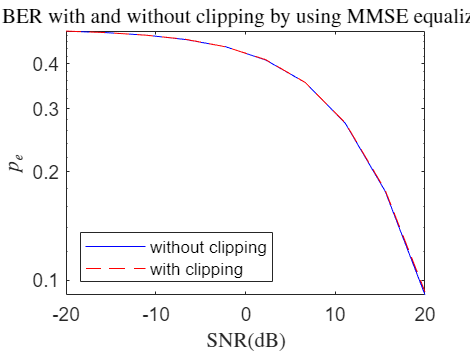

semilogy(SNR,pe_MMSE,'b',SNR,pe_MMSE_Clip,'r--');
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
legend(["without clipping", "with clipping"],'Location','southwest');
title('BER with and without clipping by using MMSE equalizer',Interpreter='latex');

# **Functions:**

function output = CP(cp, input)
    output = zeros(size(input,1),size(input,2)+cp);
    output(:,1:cp) = input(:,(end-cp+1):end);
    output(:,(1+cp):end) = input;
end

function output = CP_Removal(cp, input)
    output = input(1,(1+cp):end);
end